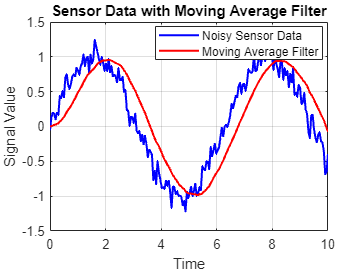

% Parameters
WINDOW_SIZE = 20;

% Initialize variables
INDEX = 1;
SUM = 0;
READINGS = zeros(1, WINDOW_SIZE);
AVERAGED = zeros(1, WINDOW_SIZE);

% Generate synthetic noisy sensor data
rng(42); % Set seed for reproducibility
time = linspace(0, 10, 200);
noise = 0.1 * randn(1, 200);
sensorData = sin(time) + noise;

% Apply moving average filter
for i = 1:length(sensorData)
    % Update running sum
    SUM = SUM - READINGS(INDEX) + sensorData(i);
    
    % Update rolling window
    READINGS(INDEX) = sensorData(i);
    
    % Increment index and wrap to 1 if it exceeds the window size
    INDEX = mod(INDEX, WINDOW_SIZE) + 1;
    
    % Calculate moving average
    AVERAGED(i) = SUM / WINDOW_SIZE;
end

% Plot original and filtered data
figure;
plot(time, sensorData, 'b', 'LineWidth', 1.5, 'DisplayName', 'Noisy Sensor Data');
hold on;
plot(time, AVERAGED, 'r', 'LineWidth', 1.5, 'DisplayName', 'Moving Average Filter');
title('Sensor Data with Moving Average Filter');
xlabel('Time');
ylabel('Signal Value');
legend('Location', 'Best');
grid on;